# Projective Geometry 

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2020-12-28

### **Points and Lines in the Homogeneous Coordinate**

**Q1: Intersection point (**$p_x$**, **$p_y$**) of the two lines **$l_1$** and **$l_2$ 

$l_1$passes trhough two distinct points, (0,1) and (1,2). 

$l_2$passes trhough two distinct points, (4,0) and (5,3). 

% method 1 (using the homogeneous coordinate representaion)
l1 = cross([0,1,1]',[1,2,1]');
l2 = cross([4,0,1]',[5,3,1]');
x = cross(l1,l2);
px = x(1)/x(3);
py = x(2)/x(3);
fprintf('(px,py) = (%1.2f, %1.2f) \n', px, py);

(px,py) = (6.50, 7.50) 


% method 2
% Line-line intersection
% https://en.wikipedia.org/wiki/Line%E2%80%93line_intersection

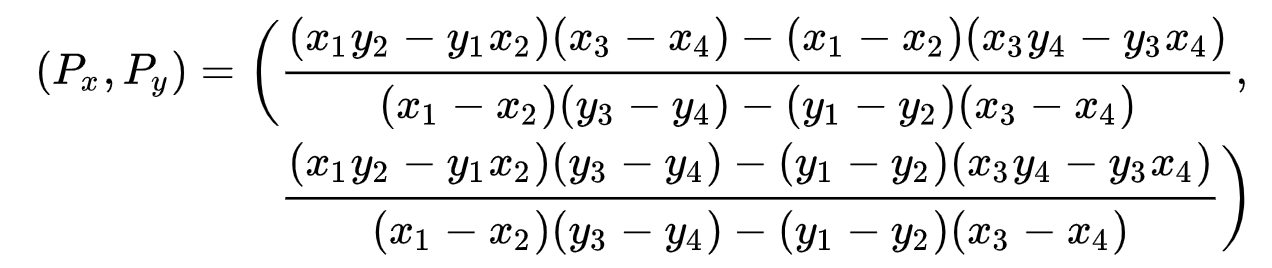

denom = (0-1)*(0-3)-(1-2)*(4-5);
numerx = (0*2-1*1)*(4-5)-(0-1)*(4*3-0*3);
numery = (0*2-1*1)*(0-3)-(1-2)*(4*3-0*3);

px = numerx/denom; 
py = numery/denom;
fprintf('(px,py) = (%1.2f, %1.2f) \n', px, py);

(px,py) = (6.50, 7.50) 


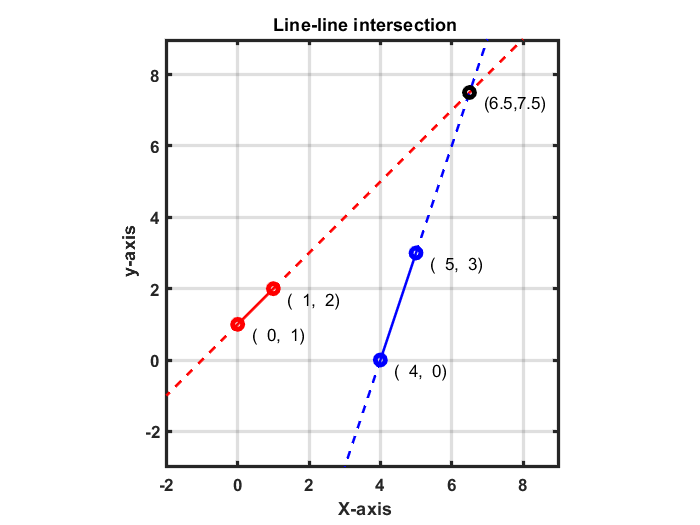

figure(1);
plot([0 1], [1, 2], 'or', 'linewidth', 3); hold on;
line([0 1], [1, 2],  'linewidth', 1.5, 'Color', 'r');
plot([4 5], [0, 3], 'ob', 'linewidth', 3);
line([4 5], [0, 3],  'linewidth',  1.5, 'Color', 'b'); 

line([1 8], [2, 9], 'Color', 'r', 'linewidth',  1.5, 'LineStyle', '--');
line([5 7], [3, 9], 'Color', 'b', 'linewidth',  1.5,  'LineStyle', '--'); 
line([0 -2], [1, -1], 'Color', 'r', 'linewidth',  1.5,  'LineStyle', '--');
line([4 3], [0, -3], 'Color', 'b',  'linewidth',  1.5, 'LineStyle', '--'); 

plot(6.5,7.5,'ok', 'linewidth', 3); 

text([0 1 4 5 6.5],[1 2 0 3 7.5],strcat('   (',num2str([0 1 4 5 6.5]'),',',num2str([1 2 0 3 7.5]'),')'),...
     'horiz','left','vert','top');hold off;

axis equal;grid on;
title('\bf Line-line intersection');
xlabel('\bf X-axis');xlim([-2 9]);
ylabel('\bf y-axis');ylim([-3 9]);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold')

### Review of Linear Algebra

Reference: Howard Anton & Rober C. Busby (2002) "Contemporary Linear Algebra"

- A nonempty set of vectors in $R^n$ is called a subspace of $R^n$ if it is closed under scalar multiplication and addition. 

- If  are vectors in $\mathbf{v_1}, \mathbf{v_2}, ....,\mathbf{v_s}$ are vectors in $R^n$, then the set of all linear combinations $$\mathbf{x} = t_1\mathbf{v_1}+t_s\mathbf{v_s}+.....+t_s\mathbf{v_s}$ is a subspace of $R^n$. The subspace $W
$of $R^n$ whose vectors satify this linear combination is called the ***span*** of $\mathbf{v_1}, \mathbf{v_2}, ....,\mathbf{v_s}$ and is denoted by $W = span \{ \mathbf{v_1}, \mathbf{v_2}, ....,\mathbf{v_s} \}$

- The row space of A, denoted by $row(A)
$, is the subspace of $R^n$ that is spanned by the row vectors of A. 

- The column space of A, denoted by $col(A)$, is the subspace of $R^n$ that is spanned by the col vectors of A. 

- The null space of A, denoted by $null(A)$, is the solution space of $A\mathbf{x}=0$. This is a subspace of $R^n$.

- The dimension of the row space of a matrix A is called the rank of A and is denoted by $rank(A)$; and the dimension of the null space of A is called the nullity of A and is denoted by $nullity(A)
$. 

- If $S$ is a nonempty set in $R^n$, then the orthogonal complement of $S
$, denoted by $S^{\bot}$, is defined to be the set of all vectors in $R^n$ that are orthogonal to every vector in $S$. 

- If $S$ is a nonempty set in $R^n$, then $S^{\bot}$ is a subspace of $R^n$. 

- If A is an m x n matrix, then the row space of A and the null space of A are orthogonal complements ($row(A)^{\bot}$ = $null(A$))

- If A is an m x n matrix, then $rank(A) + nullity(A)=n$

### Null Vector

clear; clc; close all;

% example 1
disp('example 1')

example 1


A1 = [1 1 1;2 3 1;3 2 3];
b1 = [6 9 16]';

x1 = inv(A1)*b1 % unique solution

x1 =    -1.0000
    2.0000
    5.0000



rank(A1)

ans = 3


null(A1) % null space


ans =

  3×0 empty double matrix



numel(null(A1)) % nullity

ans = 0

size(A1,2)-rank(A1) % nullity

ans = 0


[U,S,V] = svd(A1);

A1 

A1 =      1     1     1
     2     3     1
     3     2     3


S

S =     6.0422         0         0
         0    1.5751         0
         0         0    0.1051


U*S*V'

ans =     1.0000    1.0000    1.0000
    2.0000    3.0000    1.0000
    3.0000    2.0000    3.0000




% example 2
disp('example 2')

example 2


A2 = [1 1 1 -6;2 3 1 -9;3 2 3 -16];

rank(A2)

ans = 3


null(A2) % null space

ans =     0.1796
   -0.3592
   -0.8980
   -0.1796


numel(null(A2)) % nullity

ans = 4

size(A2,2)-rank(A2) % nullity

ans = 1


[U,S,V] = svd(A2);

A2 

A2 =      1     1     1    -6
     2     3     1    -9
     3     2     3   -16


S

S =    20.2217         0         0         0
         0    1.7482         0         0
         0         0    0.1575         0


U*S*V'

ans =     1.0000    1.0000    1.0000   -6.0000
    2.0000    3.0000    1.0000   -9.0000
    3.0000    2.0000    3.0000  -16.0000



A2*null(A2)

ans = 	1.0e+-15 *

    0.2220
    0.2220
    0.8882


A2*V(:,end)

ans = 	1.0e+-15 *

    0.2220
    0.2220
    0.8882



% note that V from svd function is intially transposed. Thus, we read the
% column vector(s), not row vector(s)

% since a scale is 1, the null vector is divided by the last element.
x2 = null(A2);
x2(1:3)/x2(4)

ans =    -1.0000
    2.0000
    5.0000


### Singular Value Decomposition (Application)

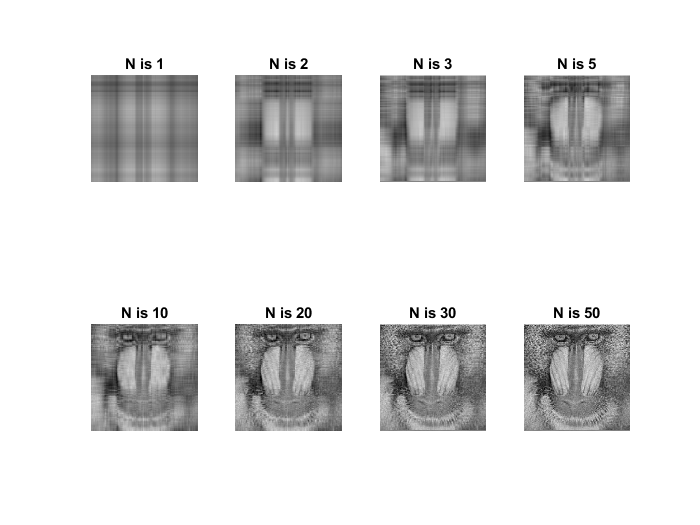

% Simple idea of how to compress an image

% SVD image compression
filenameImgG = fullfile('4.2.03.tiff'); % image filename
imgG = rgb2gray(imread(filenameImgG)); % read an image
imgGD = im2double(imgG);

% SVD on the original matrix
[U,S,V] = svd(imgGD);

% Calculate compressed matrix
figure(1);
subplot(241); N=1; imshow(U(:,1:N)*S(1:N, 1:N)*V(:,1:N)'); title(sprintf('N is %d', N))
subplot(242); N=2; imshow(U(:,1:N)*S(1:N, 1:N)*V(:,1:N)'); title(sprintf('N is %d', N))
subplot(243); N=3; imshow(U(:,1:N)*S(1:N, 1:N)*V(:,1:N)'); title(sprintf('N is %d', N))
subplot(244); N=5; imshow(U(:,1:N)*S(1:N, 1:N)*V(:,1:N)'); title(sprintf('N is %d', N))
subplot(245); N=10; imshow(U(:,1:N)*S(1:N, 1:N)*V(:,1:N)'); title(sprintf('N is %d', N))    
subplot(246); N=20; imshow(U(:,1:N)*S(1:N, 1:N)*V(:,1:N)'); title(sprintf('N is %d', N))
subplot(247); N=30; imshow(U(:,1:N)*S(1:N, 1:N)*V(:,1:N)'); title(sprintf('N is %d', N))
subplot(248); N=50; imshow(U(:,1:N)*S(1:N, 1:N)*V(:,1:N)'); title(sprintf('N is %d', N))

### Euclidean Transformation

close all;

n = 4;
[pos, adj, col_dot] = GenGrid(n); % pos:dot locations, adj: connect dots, col_dot: dot colors


**Translation: X' = X + (2, 3)'**

HE1 = eye(3,3);
HE1(1,3) = 2;
HE1(2,3) = 3;

HE1

HE1 =      1     0     2
     0     1     3
     0     0     1


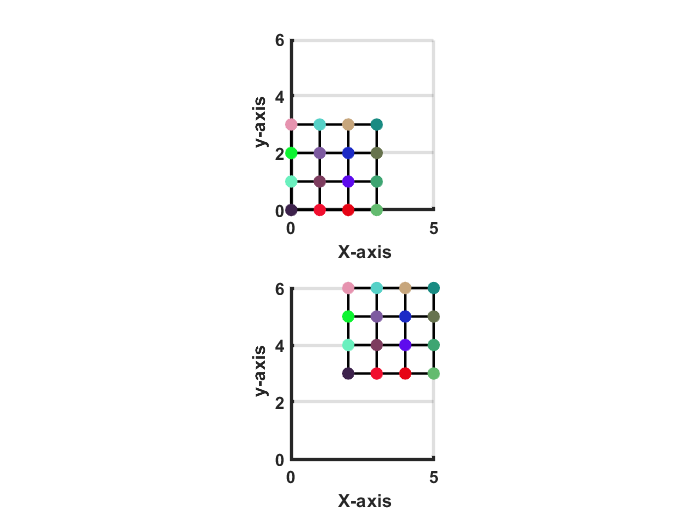


pos_new = HE1*[pos ones(n*n,1)]'; % HE1: homography matrix, [pos ones(n*n,1)]: point locations in HC
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

xylim(:,1) = min([pos_new;pos])'; % limit for drawing graphs
xylim(:,2) = max([pos_new;pos])'; % limit for drawing graphs

figure(1); 
subplot(121); DrawGrid(gca, pos, adj, col_dot, xylim);
subplot(122); DrawGrid(gca, pos_new, adj, col_dot, xylim);

**Rotation 30 degrees**

theta = 30;
HE2 = eye(3,3);
HE2(1,1) = cosd(theta);
HE2(1,2) = -sind(theta);
HE2(2,1) = sind(theta);
HE2(2,2) = cosd(theta);

HE2

HE2 =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


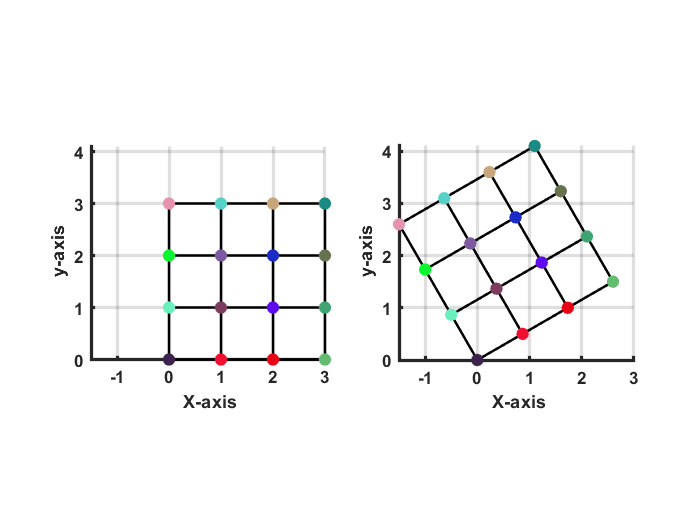


pos_new = HE2*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

xylim(:,1) = min([pos_new;pos])';
xylim(:,2) = max([pos_new;pos])';

figure(2); 
subplot(121); DrawGrid(gca, pos, adj, col_dot, xylim);
subplot(122); DrawGrid(gca, pos_new, adj, col_dot, xylim);

**Rotation 30 degrees + translation (3,4)**

theta = 30;
HE3 = eye(3,3);
HE3(1,1) = cosd(theta);
HE3(1,2) = -sind(theta);
HE3(2,1) = sind(theta);
HE3(2,2) = cosd(theta);
HE3(1,3) = 3;
HE3(2,3) = 4;

HE3

HE3 =     0.8660   -0.5000    3.0000
    0.5000    0.8660    4.0000
         0         0    1.0000


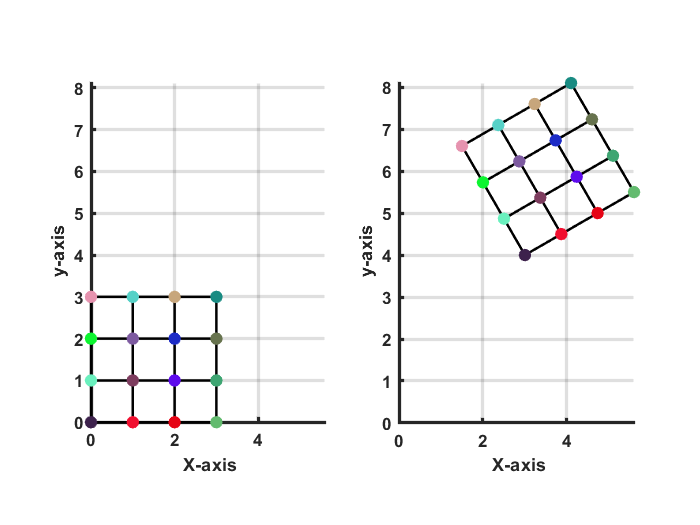


pos_new = HE3*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

xylim(:,1) = min([pos_new;pos])';
xylim(:,2) = max([pos_new;pos])';

figure(3); 
subplot(121); DrawGrid(gca, pos, adj, col_dot, xylim);
subplot(122); DrawGrid(gca, pos_new, adj, col_dot, xylim);

### Similrity Transformation

close all;

n = 4;
[pos, adj, col_dot] = GenGrid(n);

**Isometric scaling: X' = 2X **

HS1 = eye(3,3);
HS1(1,1) = 2;
HS1(2,2) = 2;

HS1

HS1 =      2     0     0
     0     2     0
     0     0     1


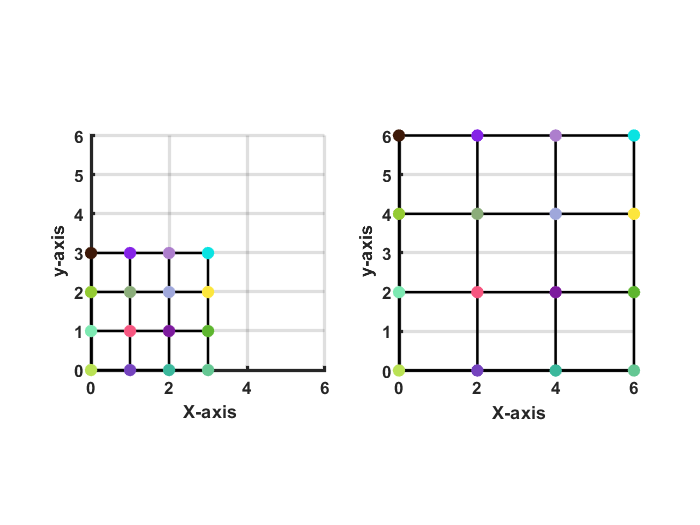


pos_new = HS1*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))'; % HC -> CA

xylim(:,1) = min([pos_new;pos])';
xylim(:,2) = max([pos_new;pos])';

figure(1); 
subplot(121); DrawGrid(gca, pos, adj, col_dot, xylim);
subplot(122); DrawGrid(gca, pos_new, adj, col_dot, xylim);

X' = 2X + rotation 30 degrees + translation (3,4)

theta = 30;
scale = 2;
HS2 = eye(3,3);
HS2(1,1) = scale * cosd(theta);
HS2(1,2) = scale * -sind(theta);
HS2(2,1) = scale * sind(theta);
HS2(2,2) = scale * cosd(theta);

HS2(1,3) = 3;
HS2(2,3) = 4;

HS2

HS2 =     1.7321   -1.0000    3.0000
    1.0000    1.7321    4.0000
         0         0    1.0000


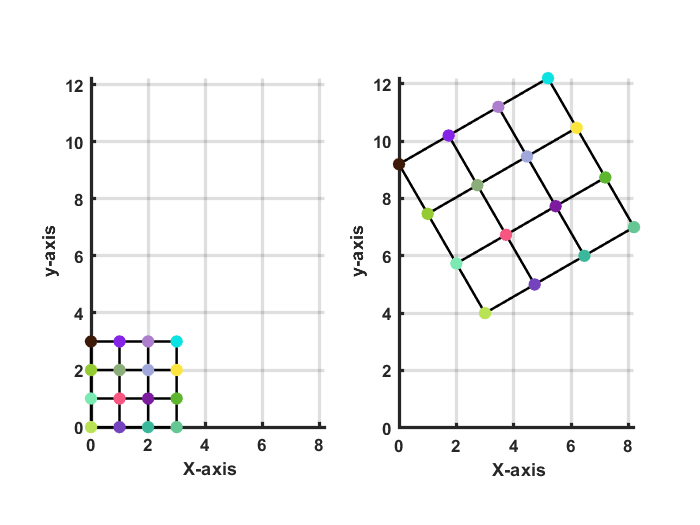


pos_new = HS2*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

xylim(:,1) = min([pos_new;pos])';
xylim(:,2) = max([pos_new;pos])';

figure(2); 
subplot(121); DrawGrid(gca, pos, adj, col_dot, xylim);
subplot(122); DrawGrid(gca, pos_new, adj, col_dot, xylim);

### **Anisotropic Scaling**

close all;

n = 4;
[pos, adj, col_dot] = GenGrid(n);

**X2 = 0.5*X1 and Y2 = 2*Y1**

HS1 = eye(3,3);
HS1(1,1) = 0.5;
HS1(2,2) = 2;

HS1

HS1 =     0.5000         0         0
         0    2.0000         0
         0         0    1.0000


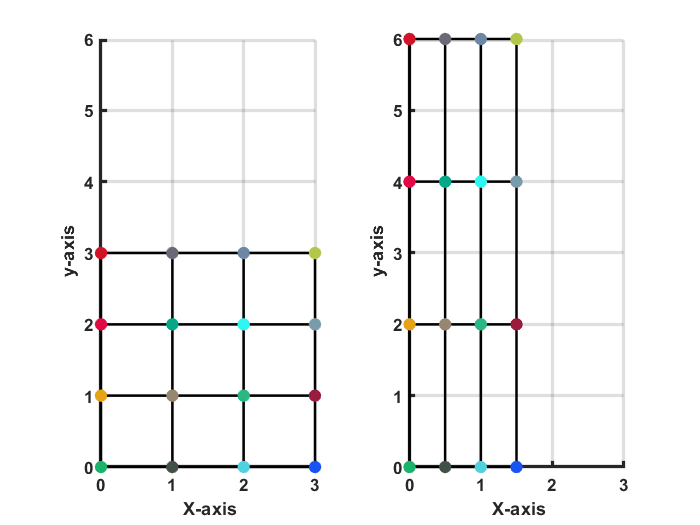


pos_new = HS1*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))'; % HC -> CA

xylim(:,1) = min([pos_new;pos])';
xylim(:,2) = max([pos_new;pos])';

figure(1); 
subplot(121); DrawGrid(gca, pos, adj, col_dot, xylim);
subplot(122); DrawGrid(gca, pos_new, adj, col_dot, xylim);

### **Affine Transformation**

clear; close all;

n = 4;
[pos, adj, col_dot] = GenGrid(n);

% random generation A: 2 x 2
A = [2 -0.534; 0.1916 0.5265]; 
HA = eye(3,3);
HA(1:2,1:2) = A;

det(A) % should be non-zero

ans = 1.1553


[U, D, V] = svd(A);

if det(U)<0 && det(V)<0  % reflection correction
    U = U*[-1 0;0 1];
    V = V*[-1 0;0 1];
end
A = U*D*V'

A =     2.0000   -0.5340
    0.1916    0.5265



% check that all three angles are correct. This means it's a rotation matrix
R_theta = U*V'; 
acosd(R_theta(1,1))

ans = 16.0238

asind(-R_theta(1,2))

ans = 16.0238

asind(R_theta(2,1))

ans = 16.0238

theta = acosd(R_theta(1,1));

% check that all three angles are correct. This means it's a rotation matrix
R_phi = V';
acosd(R_phi(1,1))

ans = 14.5528

asind(-R_phi(1,2))

ans = 14.5528

asind(R_phi(2,1))

ans = 14.5528

phi = acosd(R_phi(1,1));


**A = Rt*Rp'*Dn*Rp**

Rt = eye(3,3);
Rt(1,1) = cosd(theta);
Rt(2,2) = cosd(theta);
Rt(1,2) = -sind(theta);
Rt(2,1) = sind(theta);

Rp = eye(3,3);
Rp(1,1) = cosd(phi);
Rp(2,2) = cosd(phi);
Rp(1,2) = -sind(phi);
Rp(2,1) = sind(phi);

Dn = eye(3,3);
Dn(1:2,1:2) = D;

% both balues are the same
HA

HA =     2.0000   -0.5340         0
    0.1916    0.5265         0
         0         0    1.0000


Rt*Rp'*Dn*Rp

ans =     2.0000   -0.5340         0
    0.1916    0.5265         0
         0         0    1.0000


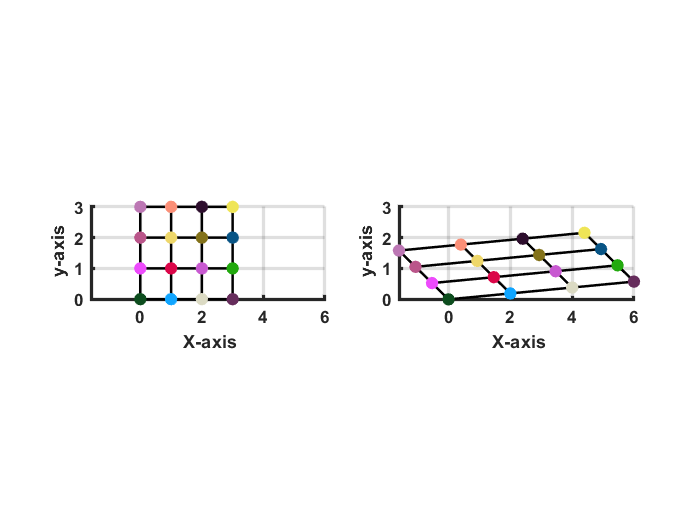


pos_new = HA*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

xylim(:,1) = min([pos_new;pos])';
xylim(:,2) = max([pos_new;pos])';

figure(1); 
subplot(121); DrawGrid(gca, pos, adj, col_dot, xylim);
subplot(122); DrawGrid(gca, pos_new, adj, col_dot, xylim);

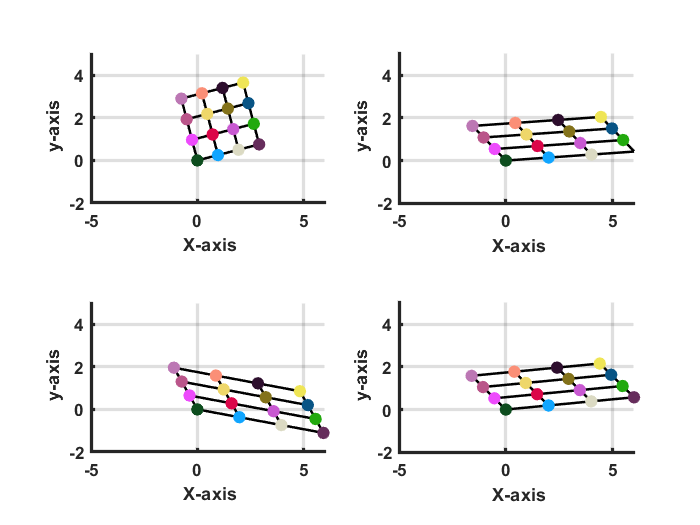



figure(2);
pos_new = Rp*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

subplot(221); DrawGrid(gca, pos_new, adj, col_dot, xylim);

pos_new = Dn*Rp*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';
xlim([-5 6]); ylim([-2 5])

subplot(222); DrawGrid(gca, pos_new, adj, col_dot, xylim);

pos_new = Rp'*Dn*Rp*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';
xlim([-5 6]); ylim([-2 5])

subplot(223); DrawGrid(gca, pos_new, adj, col_dot, xylim);

pos_new = Rt*Rp'*Dn*Rp*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';
xlim([-5 6]); ylim([-2 5])

subplot(224); DrawGrid(gca, pos_new, adj, col_dot, xylim);
pos_new_svd = pos_new;
xlim([-5 6]); ylim([-2 5])

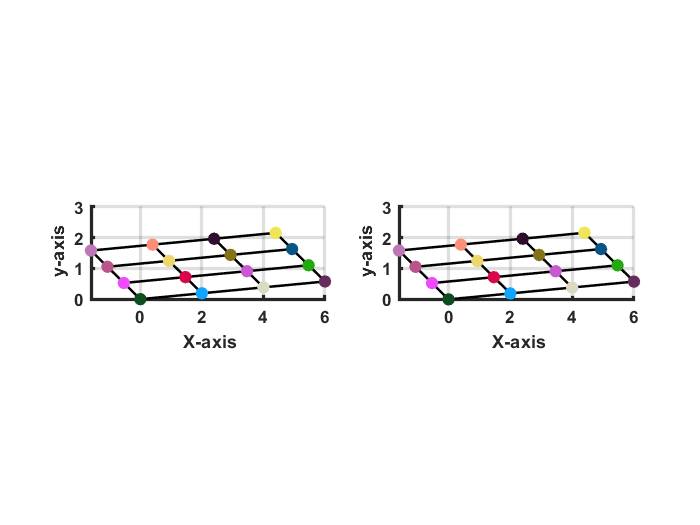


figure(3); 
% both graphs are the same
pos_new = HA*[pos ones(n*n,1)]';
pos_new = bsxfun(@rdivide, pos_new(1:2,:), pos_new(3,:))';

subplot(121); DrawGrid(gca, pos_new_svd, adj, col_dot, xylim);
subplot(122); DrawGrid(gca, pos_new, adj, col_dot, xylim);

### Point Correspondance for Estimating a Homography

syms h11 h12 h13 h21 h22 h23 h31 h32 h33
syms x y x_p y_p
H = [h11 h12 h13;h21 h22 h23;h31 h32 h33];
x = [x;y;1];
xp = [x_p;y_p;1];

Hx = H*x;
eqn1 = Hx(1)-xp(1)/xp(3)*Hx(3) == 0;
eqn2 = Hx(2)-xp(2)/xp(3)*Hx(3) == 0;

[A1, b1] = equationsToMatrix(eqn1, [h11;h12;h13;h21;h22;h23;h31;h32;h33])

$$A1 = \left(\begin{array}{ccccccccc} x & y & 1 & 0 & 0 & 0 & -x\,x_{p} & -x_{p}\,y & -x_{p} \end{array}\right)$$

$$b1 = \left(\begin{array}{c} 0 \end{array}\right)$$

[A2, b2] = equationsToMatrix(eqn2, [h11;h12;h13;h21;h22;h23;h31;h32;h33])

$$A2 = \left(\begin{array}{ccccccccc} 0 & 0 & 0 & x & y & 1 & -x\,y_{p} & -y\,y_{p} & -y_{p} \end{array}\right)$$

$$b2 = \left(\begin{array}{c} 0 \end{array}\right)$$